# Plotting Data

### Line Plot

x = linspace(0, 2*pi, 500);
y = sin(x);

% PLOT DATA
plot(x, y);

### Title and Labels

% TITLE
title("SINE CURVE");
xlabel("X");
ylabel("Y");

### xlim, ylim

xlim([0, 2*pi]);
ylim([-1.5, 1.5]);

### hold, legend

z = cos(x);
hold on;
plot(x, z);
hold off;
legend(["SINE", "COSINE"]);

### Line Style

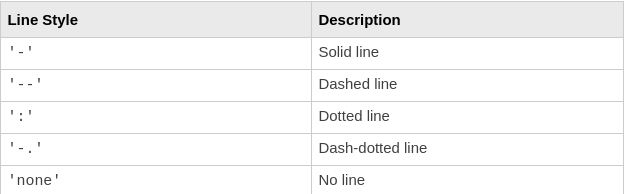

plot(x, y, '--');

### Line Color

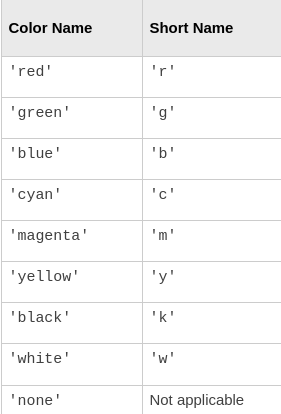

plot(x, y, 'b--');

### Line Width

plot(x, y, 'LineWidth', 2);

### Subplots

subplot(2, 1, 1);
plot(x, y);
subplot(2, 1, 2);
plot(x, y);

# More Plots

### Bar Plot

x = [1, 5, 3, 6, 7, 9, 4];
bar(x);

x = rand(4, 2);
bar(x)

### Scatter Plot

x = rand(1, 20);
y = rand(1, 20);
scatter(x, y, 20, 'Marker',"o", 'MarkerFaceColor', 'b')

### Boxplot

load carsmall
boxplot(MPG, Origin);

### Surface Plot

y = -10:0.5:10;
x = -10:0.5:10;
[X, Y] = meshgrid(x, y);
Z = sin(sqrt(X.^2+Y.^2)) ./ sqrt(X.^2+Y.^2);
surfc(X, Y, Z)

### MATLAB Plot Gallery

`Visit this link for more plots : `[`MATLAB Plot Gallery`](https://www.mathworks.com/products/matlab/plot-gallery.html)

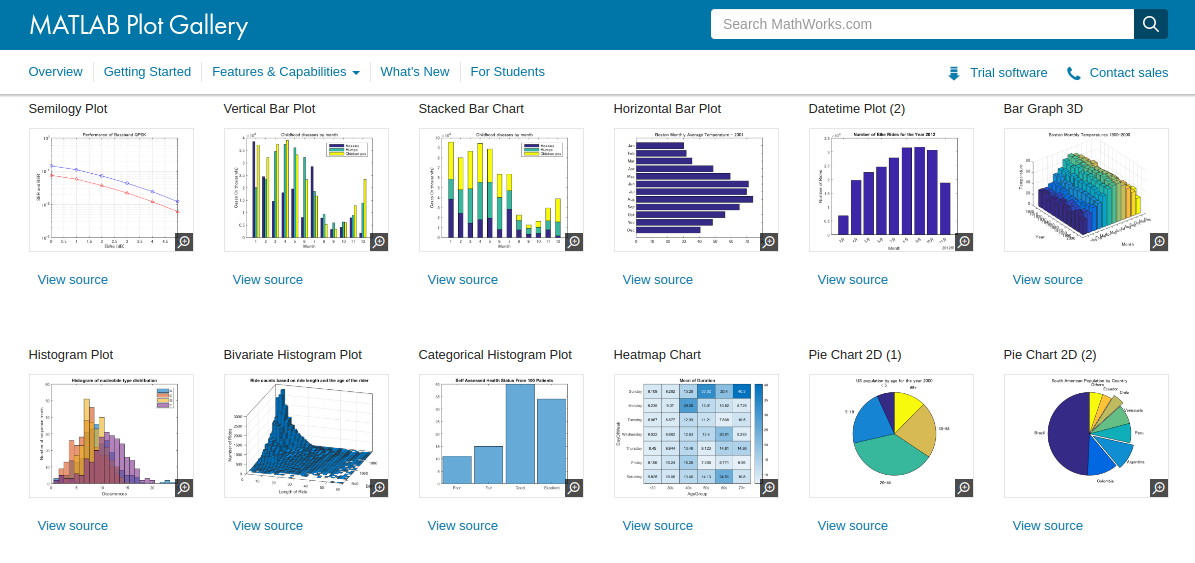

# Curve Fitting

### Liner 

% BASE EQUATION : y = mx + c
m = 1.5;
c = 2;

x = 0 : 0.2 : 10;
y = m * x + c;
scatter(x, y);

% ADD NOISE
y_noisy = y + randi([-5, 5], size(x));

scatter(x, y_noisy);

### Non-Linear

% BASE EQUATION : y = ax^2 + bx + c
a = 2;
b = -10;
c = 0.5;

y = a * x.^2 + b * x + c;
scatter(x, y);

% ADD NOISE
y_noisy = y + randi([-10, 10], size(x));

scatter(x, y_noisy);

# Branch and Loop

### BRANCHING

a = 7;
if a > 5
    disp("A > 5")
else
    disp("A <= 5")
end

### LOOPING

for i = 1 : 10
    disp(i);
end


$$y=\sum_{n\;=\;0}^N nx^2$$


N = 100;
x = 3;

y = 0;
for n = 0 : 100
    y = y + n * x ^ 2;
end
y

`Given, `


$$m=\left\lbrack m_1 \;\;\;\;m_2 \right\rbrack$$



$$x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\ldotp \ldotp \\
x_n 
\end{array}\right\rbrack$$


`Find, `


$$y=\left\lbrack \begin{array}{c}
m_0 +m_1 x_1 \\
m_0 +m_1 x_2 \\
\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \\
m_0 +m_1 x_n 
\end{array}\right\rbrack$$


n = 100;

m = [2, 3];

x = rand(n, 1);

y = zeros(size(x));

for i = 1 : n
    y(i) = m(1) + m(2) * x(i);
end

# Functions

### SYNTAX

**NOTE :**` Function name must be the same as the ``filename`

x = linspace(-10, 10, 100);
y = myFunction(x);
plot(x, y);

# Function Example

This function performs the following action


$$y\;=\;f\left(x\right)\;=\frac{1}{1+e^{-x} }$$


function y = myFunction(x)
    y = 1 ./ (1 + exp(-x));
end

# Fequency Domain Analysis

### Fourier Series

`A Fourier series is an expansion of a ``periodic`` function in terms of an infinite sum of ``sines`` and ``cosines``.`

N = 16;

t = linspace(0, 2 * pi, 300);
y = zeros(size(t));
for i = 1 : 2 : N
    y = y + (1 / i) * sin(i * t);
end

plot(t, y, 'LineWidth', 2);
grid on;
xlim([0, 2 * pi]);
ylim([-1.5, 1.5]);
title("FOURIER SERIES");

### Fourier Transform

`Decomposes a non-periodic signal into its frequency components. `

`The Discrete Fourier Transfrom (DFT)`` of a signal x[n] is given by-`

`Fast Fourier Transform (FFT)`` is an algorithm that performs the forurier transform of a function in a efficient way. You can use the MATLAB ``fft()`` function to perform discrete fourier transform.`

f1 = 100;
f2 = 200;
Fs = 1000;
T = 0.1;
L = Fs * T;
t = linspace(0, T, L);
x = 0.7*sin(2*pi*f1*t) + sin(2*pi*f2*t);
plot(t, x);
title("Time Domain Signal")
xlabel("time (s)");
ylabel("Amplitude");

X = fft(x);
P = abs(X / L);
P1 = P(1 : L / 2);
F = (0 : L / 2 - 1) * (Fs / L);
plot(F, P1);

### WELCH METHOD

`You can get the power spectral density (PSD) of a signal using the ``pwelch()`` function.`

[X, F] = pwelch(x, L, L / 2, 1000, Fs, 'power');
plot(F, X);
title("Power Spectral Dessity")
xlabel("Frequency (Hz)");
ylabel("Power")

# Filter Design

`Filtering means removing unwanted components from a signal. There are mainly 4 types of filter:`

- `High-Pass Filter`

- `Low-Pass Filter`

- `Band-Pass Filter`

- `Band-Stop Filter`

`Depending on the filter architechture there are mainly 3 types of filter:`

- `Moving Average Filter`

- `Finite Impulse Response (FIR) Filter`

- `Infinite Impulse Response (IIR) Filter`

### `MOVING AVERAGE FILTER`

t = linspace(0, 2 * pi);
x = sin(t);
% ADDING NOISE
x(20) = x(20) + 0.7;
x(70) = x(70) - 0.7;
plot(t, x, 'LineWidth', 2);
title("Noisy Signal");

WL = 3;
XF = zeros(1, length(x) - WL);
for i = WL : length(x)
    % XF(i - WL + 1) = sum(x(i - WL + 1 : i)) / WL;
    XF(i - WL + 1) = median(x(i - WL + 1 : i));
end

plot(t(WL:end), XF, "LineWidth", 2);

### LOW PASS FILTER

load ecg;
plot(ecg);
xlim([0, 2000])
x = ecg + 0.1 * randn(size(ecg));
plot(x);
xlim([0, 2000])
xf = filter(Hd, x);
plot(xf);
xlim([0, 2000])

### HIGH PASS FILTER

N = 1000;
x1 = 0.1 * randn(N/2, 1);
x2 = randn(N/2, 1);
x1 = x1 + 5;
plot([x1; x2])

xf = filter(Hd, [x1; x2]);
plot(xf);